# Raibert Hopper Simulation

clear;clc;

slip.m = 1; % Mass on top of the spring
slip.l0 = 1;
slip.k = 100; % Spring Constant

fps = 10;
deltat = 5;

% Initial Guess
q0 = [0 1.5 0.2 0]; % At Apex
% q0 = [0 1.3509 1.0920 0]; % Known Fixed Point
slip.th = asin(q0(3)*pi*sqrt(slip.m/slip.k)/(2*slip.l0)); % Initial Angle

## Raibert Foot Placement Control

Kp = 0.024;
% vdes = [q0(3) 0.5 0.3 0.1 0 0 0.3 0.3 0.5 0.5 0.5 0.7 0.7 0.7 0.7];
% vdes = [q0(3) 0.6 0.5 0.4 0.2 0 0 0.2 0.5 0.8 1];
vdes = [q0(3) 0.4 0.4 0.6 0.6 0.8 0.8 0.6 0.6 0.4 0.4 0.2 0.2 0 0 0 0];
% vdes = [q0(3) 0.4 0.4 0.6 0.6 0.6 0.6 0.6 0.6];
control = @(xd,xd_des) asin(xd*pi*sqrt(slip.m/slip.k)/(2*slip.l0)) + Kp*(xd-xd_des);

## Integrate

n = length(vdes); % Number of steps
tsim = [];
qsim = [];
v_apex = [];
tstart = 0;

for k=1:n
    [t,q,q0next] = one_step(tstart,deltat,q0,slip,control,vdes(k));
    v_apex = [v_apex q0next(3)];
    tq = linspace(t(1),t(end),fps)';
    qq(:,1) = interp1(t,q(:,1),tq);
    qq(:,2) = interp1(t,q(:,2),tq);
    qq(:,3) = interp1(t,q(:,3),tq);
    qq(:,4) = interp1(t,q(:,4),tq);
    qq(:,5) = interp1(t,q(:,5),tq);
    qq(:,6) = interp1(t,q(:,6),tq);
    tsim = [tsim; tq(1:end-1,:)];
    qsim = [qsim; qq(1:end-1,:)];
    q0 = q0next(1:4);
    slip.th = q0next(5);
    tstart = tsim(end,:);
end

## Animate

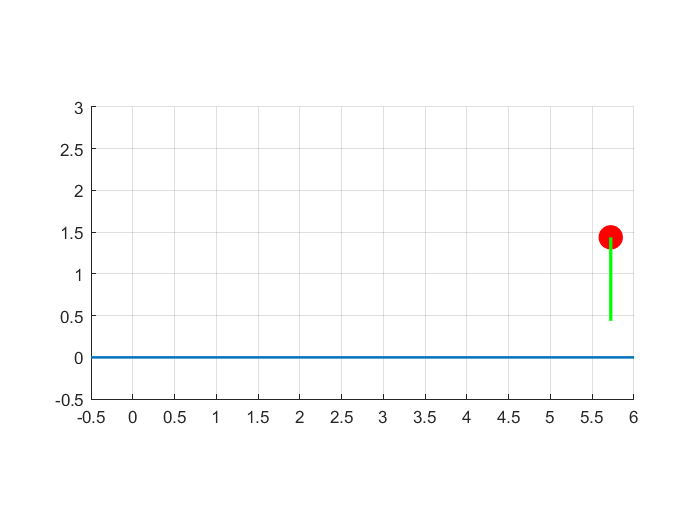

L = 6;

figure(1);
for k=1:length(tsim)
    qk = qsim(k,1:4);
    foot = qsim(k,5:6);
    
    hold on;
    grid on;
    h1 = line([-0.5 L],[0 0],'LineWidth',1.5); % Ground
    h2 = plot(qk(1),qk(2),'.','MarkerSize',50,'Color','red'); % Point Mass
    h3 = line([qk(1) foot(1)],[qk(2) foot(2)],'LineWidth',2,'Color','green'); % Spring
    
    axis([-0.5 L -0.5 L/2]);
    xticks(-0.5:0.5:L);
    yticks(-0.5:0.5:L);
    daspect([1 1 1]);
    drawnow;
    
    pause(0.05);
    if k ~= length(tsim)
        delete(h1);
        delete(h2);
        delete(h3);
    end 
end

## Plot SLIP Paramaters

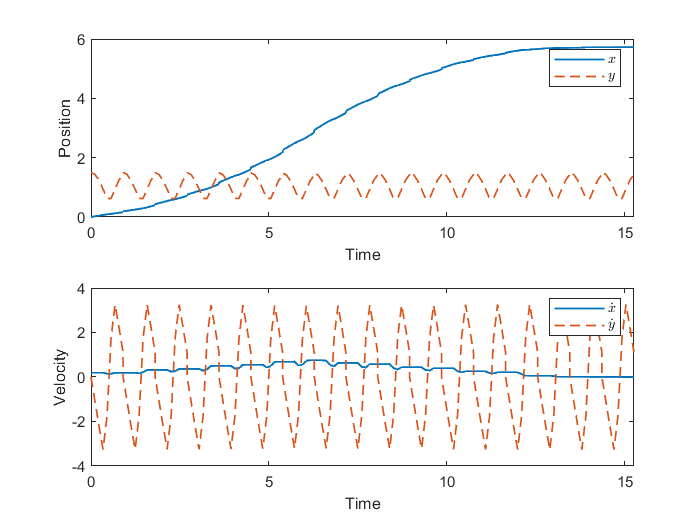

figure(2);
subplot(2,1,1);
plot(tsim,qsim(:,1),'LineWidth',1);
hold on;
plot(tsim,qsim(:,2),'--','LineWidth',1);
ylabel('Position');
xlabel('Time');
axis([0 tsim(end) 0 6]);
legend({'$x$', '$y$'}, 'Interpreter', 'latex');
subplot(2,1,2);
plot(tsim,qsim(:,3),'LineWidth',1);
hold on;
plot(tsim,qsim(:,4),'--','LineWidth',1);
ylabel('Velocity');
xlabel('Time');
axis([0 tsim(end) -4 4]);
legend({'$\dot{x}$', '$\dot{y}$'}, 'Interpreter', 'latex');

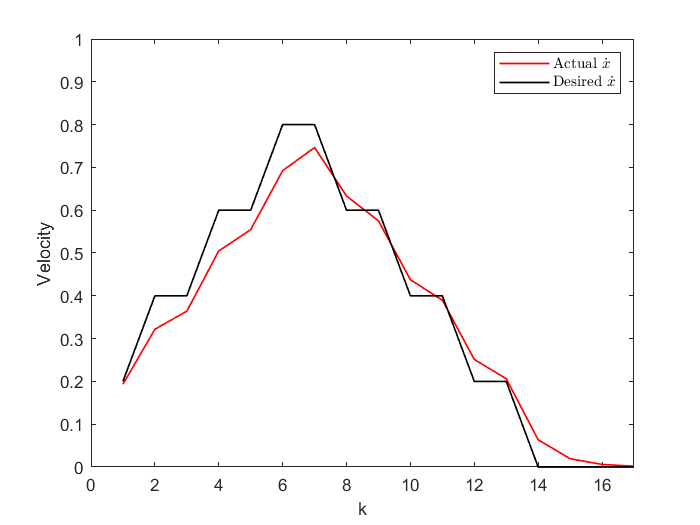

figure(3);
plot(v_apex,'LineWidth',1,'Color','red');
hold on;
plot(vdes,'LineWidth',1,'Color','black');
ylabel('Velocity');
xlabel('k');
axis([0 length(v_apex) 0 max(vdes)+0.2])
legend({'Actual $\dot{x}$', 'Desired $\dot{x}$'}, 'Interpreter', 'latex');